%%Assignment-2
syms s


%System Parameters
m1 = 1e-3; %mass of the lens, m1, kg
m2 = 100e-3; %mass of the frame, m2, kg
x_dist = 200e-6; %amplitude of disturbance from fixed world to the frame, m
f_dist = 25; %natural frequency of the system that connects frame to the fixed world, Hz
w_dist = 2*pi*f_dist;%f_dist, rad/s
x_error = 0.2e-6; %amplitude of allowed error, m

%calculating stiffness between a)world and frame, and b)frame and lens
k2 = m2*(w_dist^2); %stiffness between world and the frame
k1 = (m1*(w_dist^2)*x_dist)/x_error; %stiffness between frame and lens

%adding damping for god's love
zeta = 0.05;
c1 = 2*zeta*sqrt(k1*m1);
c2 = 2*zeta*sqrt(k2*m2);

%equation #2 rearranged to solve for Kp
Kp = m1*(w_dist^2)*((x_dist/x_error)-1);

%equation #3 rearranged to solve for f_bw
f_bw = f_dist*sqrt((x_dist/x_error));

%calculating Td = 1/wd for derivative control
f_d = f_bw/3;
w_d = 2*pi*f_d;
T_d = 1/w_d;
%Calculating w_i
f_i = f_bw/10;
w_i = 2*pi*f_i;
T_i = 1/w_i;
%Calculating w_t
f_t =f_bw*3;
w_t =2*pi*f_t

w_t = 1.4902e+04

T_t = 1/w_t

T_t = 6.7106e-05

s = tf('s');

%Initial PD_controller
PD_controller = Kp*(1+T_d*s);
%PID_controller = Kp*()


load("Assignment_2_linearizer.mat");

Linsys1 = LinearAnalysisToolProject.Results(1).Data.Value; % P = 0
Linsys2 = LinearAnalysisToolProject.Results(2).Data.Value; % P = Kp
Linsys3 = LinearAnalysisToolProject.Results(3).Data.Value; % PD
Linsys4 = LinearAnalysisToolProject.Results(4).Data.Value; % PD, with Kp/3
Linsys5 = LinearAnalysisToolProject.Results(5).Data.Value; % PID

%bode plot config
opts = bodeoptions("cstprefs");
opts.FreqUnits = ('Hz');
opts.MagUnits = ('abs');
opts.Grid = ('on');
opts.MagScale = ('log');

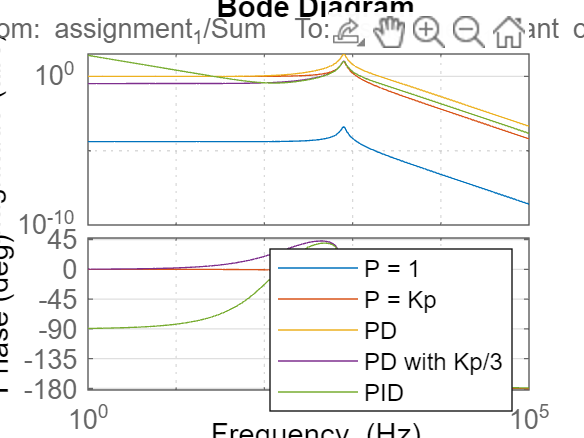


%Plotting controllers all together
figure;
bode(Linsys1,Linsys2,Linsys3,Linsys4,Linsys5,opts)
legend('P = 1','P = Kp','PD','PD with Kp/3','PID')

Kp_plot = 1/real(freqresp(Linsys1,25,'Hz'))

Kp_plot = 2.4625e+04

mag_kp = freqresp(Linsys1,25,'Hz')

mag_kp = 4.0609e-05 - 1.3270e-07i

Kp_diff = Kp-Kp_plot

Kp_diff = 24.1668

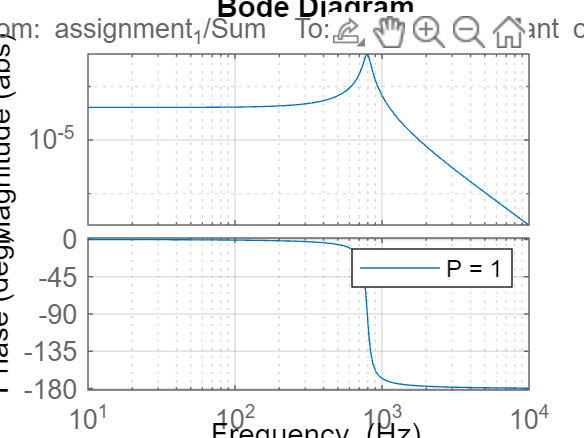

%Plotting P = 1
figure;
bode(Linsys1,opts)
legend('P = 1')

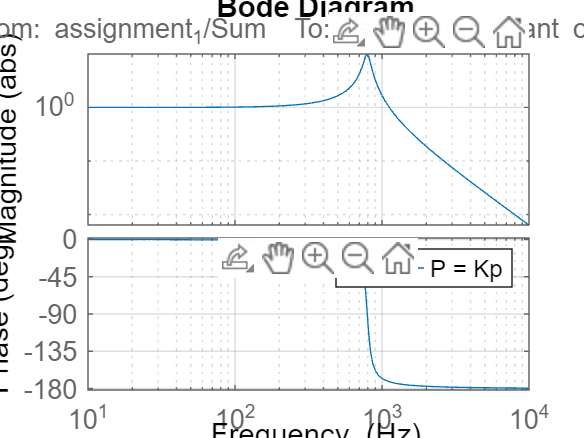


%Plotting P = Kp
figure;
bode(Linsys2,opts)
legend('P = Kp')

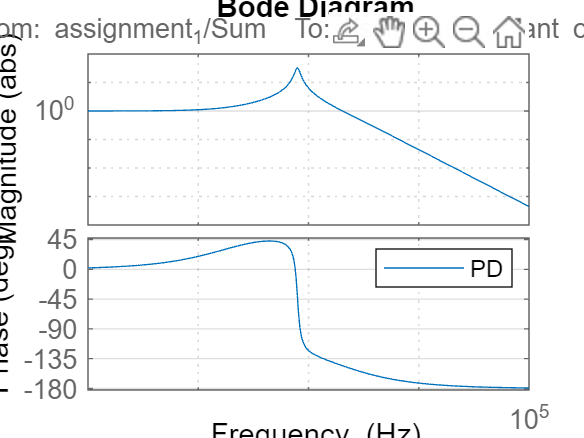

%Plotting PD
figure;
bode(Linsys3,opts)
legend('PD')

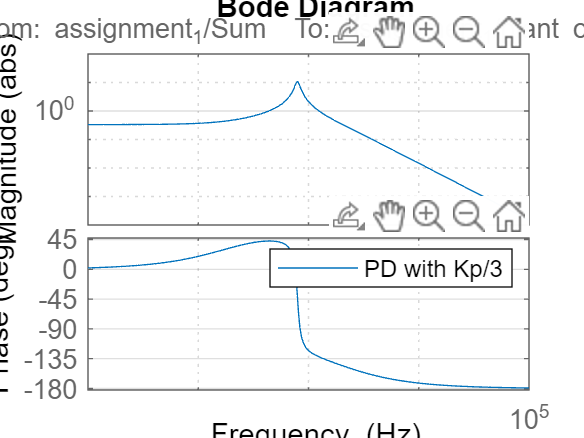

%Plotting PD Kp/3
figure;
bode(Linsys4,opts)
legend('PD with Kp/3')

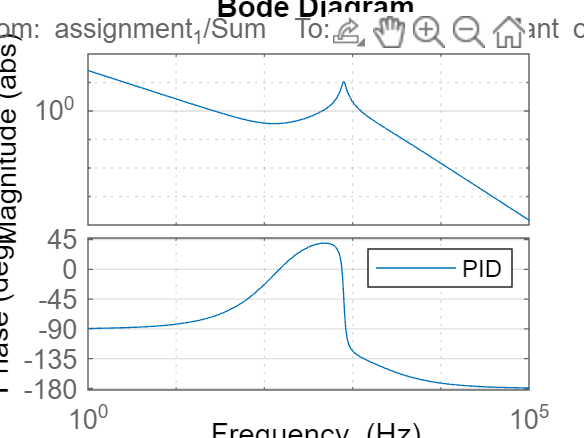

%Plotting PID
figure;
bode(Linsys5,opts)
legend('PID')

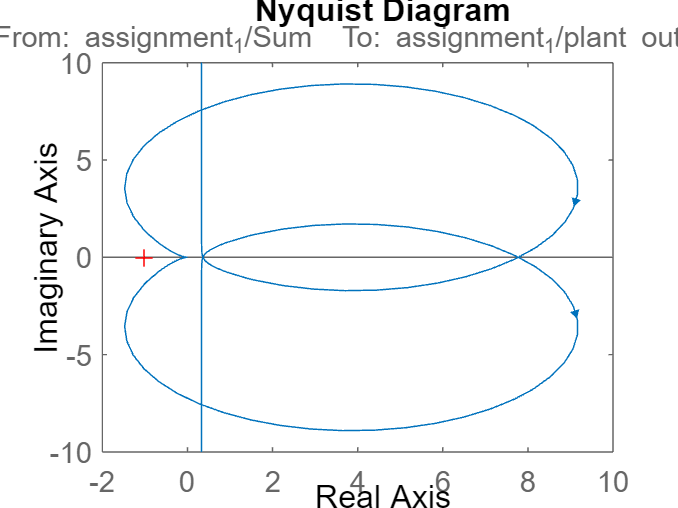


%Plotting nyquist plot
figure;
nyquist(Linsys5);

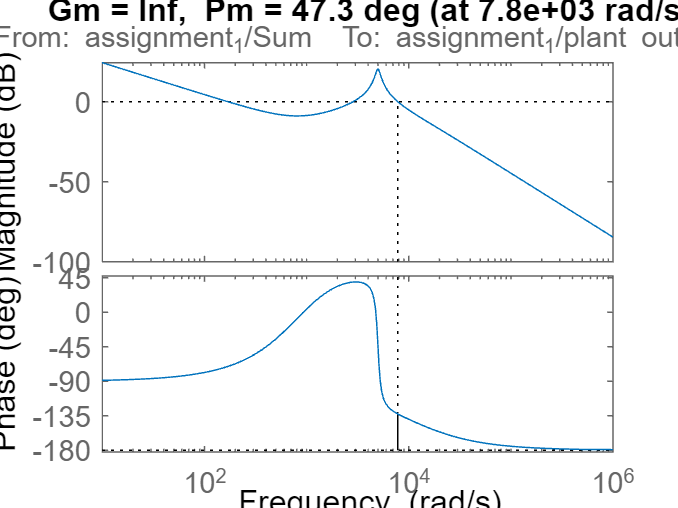

%Getting stability margins (GM & PM)
figure;
margin(Linsys5);


%%% Q13 - Q15 %%%%%

%Adding transport and limit on motor bandwidth
%Tdelay = 1e-6; %Delay
Tdelay = 10e-6; %Delay2 uncomment for Q15
f_mbw = 50e3; %Limited motor bandwitdth
%f_mbw = 3e3; %Limited motor bandwitdth 2 - Uncomment for Q14
%f_mbw = 750;
w_mbw = 2*pi*f_mbw;
T_mbw = 1/w_mbw;
PadeFilter = 1/(1+T_mbw*s)^2;


%Load linearizer for the system with transport delay and the filter
Linearize_2 = load("Assignment_2_linearizer_2.mat");
Linsys6 = Linearize_2.LinearAnalysisToolProject.Results(1).Data.Value; % Delay 1, bandwidth 50k
Linsys7 = Linearize_2.LinearAnalysisToolProject.Results(2).Data.Value; % Delay 1, bandwidth 3k
Linsys8 = Linearize_2.LinearAnalysisToolProject.Results(3).Data.Value; % Delay 10,bandwidth 50k
q14_bw = Linearize_2.LinearAnalysisToolProject.Results(9).Data.Value;

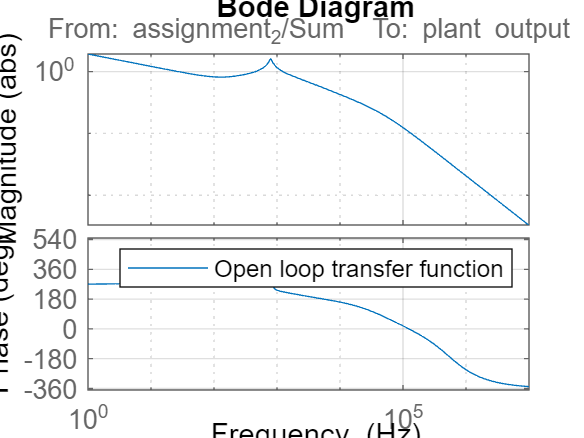

%%Q13
%Plotting the open loop transfer function
figure;
bode(Linsys6,opts);
legend('Open loop transfer function')

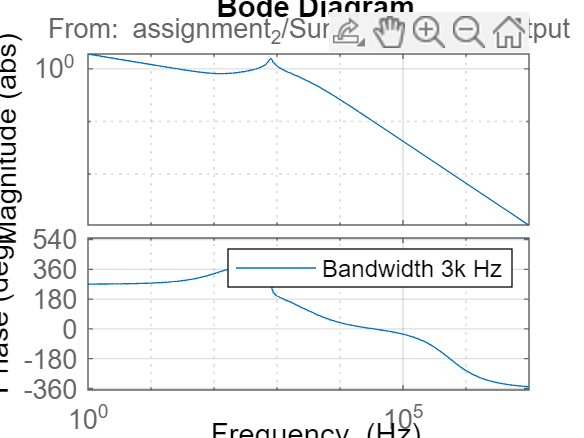

%%Q14
%Plotting 3kHz first
figure;
bode(Linsys7,opts)
legend('Bandwidth 3k Hz')

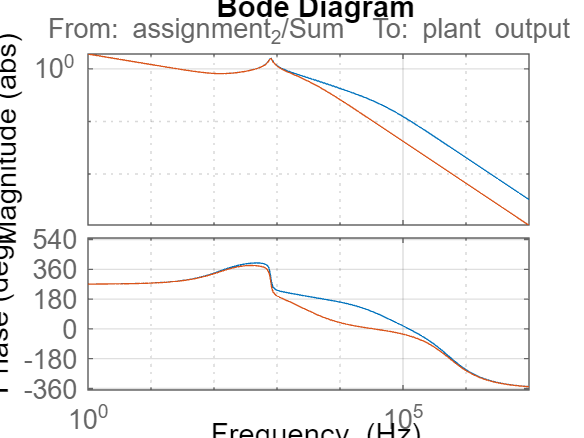

%Plotting the comparison
figure;
bode(Linsys6,Linsys7,opts)

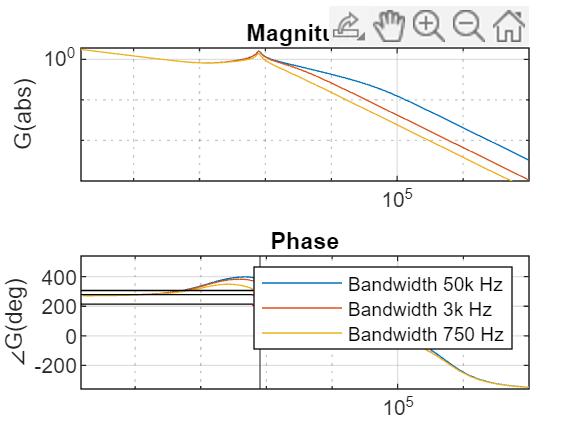

%% Making Q14 plot. Dont look just accept.

[mag1,phase1,wout1] = bode(Linsys6);
[mag2,phase2,wout2] = bode(Linsys7);
[mag3,phase3,wout3] = bode(q14_bw);
f1 = wout1/(2*pi);
f2 = wout2/(2*pi);
f3 = wout3/(2*pi);
mag1 = squeeze(mag1);
mag2 = squeeze(mag2);
mag3 = squeeze(mag3);
phase1 = squeeze(phase1);
phase2 = squeeze(phase2);
phase3 = squeeze(phase3);
figure;

ax1 = subplot(2,1,1);
loglog(f1,mag1); hold on;
loglog(f2,mag2); hold on;
loglog(f3,mag3);
grid on;
ylabel('G(abs)');
title('Magnitude')
ylim([10^(-15) 25])
xlim([0 10000000])

ax2 = subplot(2,1,2);
semilogx(f1,phase1); hold on;
semilogx(f2,phase2); hold on;
semilogx(f3,phase3); hold on;
bwline = xline(800); hold on
%Define a vector to use with the intersections command
% have to install online
bwline_intersection = zeros(length(phase1),2);
bwline_intersection(:,1) = 800;
bwline_intersection(:,2) = linspace(-400,540,142);
[xint1,yint1] = intersections(bwline_intersection(:,1),bwline_intersection(:,2),f1,phase1);
[xint1,yint2] = intersections(bwline_intersection(:,1),bwline_intersection(:,2),f2,phase2);
[xint1,yint3] = intersections(bwline_intersection(:,1),bwline_intersection(:,2),f3,phase3);

plot([1.5 800], [yint1 yint1],"k"); hold on;
plot([1.5 800], [yint2 yint2],"k"); hold on;
plot([1.5 800], [yint3 yint3],"k"); hold on;
plot(xint1,yint2,'r*'); hold on;
plot(xint1,yint2,'r*'); hold on;
plot(xint1,yint3,'r*');
text(xint1,yint1,['(',num2str(xint1),',',num2str(yint1),')'],'FontSize',6)
text(xint1,yint2,['(',num2str(xint1),',',num2str(yint2),')'],'FontSize',6)
text(xint1,yint3,['(',num2str(xint1),',',num2str(yint3),')'],'FontSize',6)

grid on;
ylabel('\angleG(deg)');
title('Phase')
ylim([-360 540])
xlim([0 10000000])
legend('Bandwidth 50k Hz','Bandwidth 3k Hz', 'Bandwidth 750 Hz')

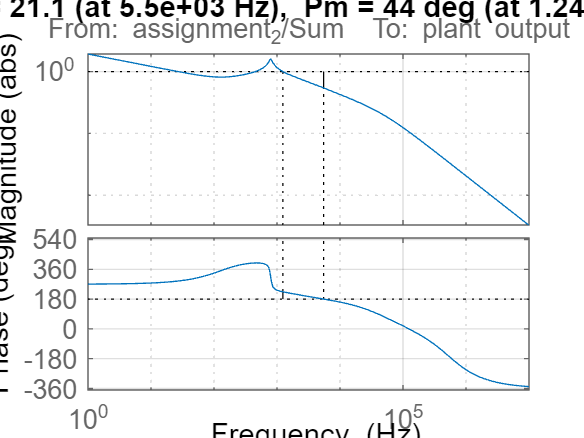

figure;
margin(Linsys6,opts)


%Getting phase margin of the open loops
[Gm1,Pm1,Wcg1,Wcp1] = margin(Linsys6);
[Gm2,Pm2,Wcg2,Wcp2] = margin(Linsys7);
disp(Pm1)

   44.0260



disp(Pm2)

    5.5771



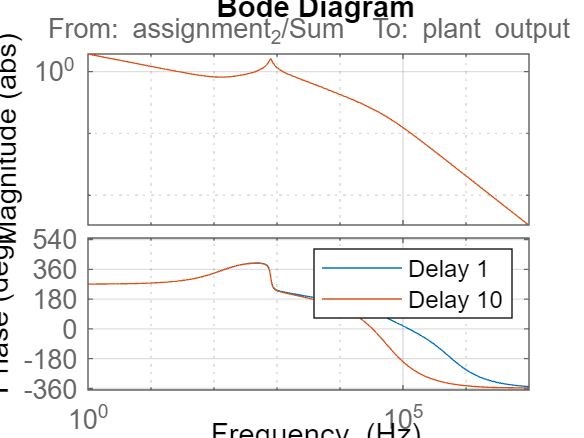


%Q15

%Plotting the comparison
figure;
bode(Linsys6,Linsys8,opts)
legend('Delay 1','Delay 10')


%Getting phase margin of the open loop
[Gm3,Pm3,Wcg3,Wcp3] = margin(Linsys8);
disp(Pm1)

   44.0260



disp(Pm3)

   40.0042



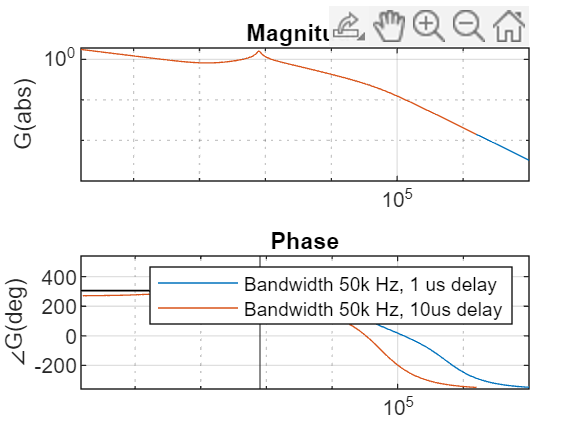


%% Making Q15 plot. Dont look just accept.
[mag1,phase1,wout1] = bode(Linsys6);
[mag2,phase2,wout2] = bode(Linsys8);
f1 = wout1/(2*pi);
f2 = wout2/(2*pi);
mag1 = squeeze(mag1);
mag2 = squeeze(mag2);
phase1 = squeeze(phase1);
phase2 = squeeze(phase2);
figure;

ax1 = subplot(2,1,1);
loglog(f1,mag1); hold on;
loglog(f2,mag2); 
grid on;
ylabel('G(abs)');
title('Magnitude')
ylim([10^(-15) 25])
xlim([0 10000000])

ax2 = subplot(2,1,2);
semilogx(f1,phase1); hold on;
semilogx(f2,phase2); hold on;

bwline = xline(800); hold on
%Define a vector to use with the intersections command
% have to install online
bwline_intersection = zeros(length(phase1),2);
bwline_intersection(:,1) = 800;
bwline_intersection(:,2) = linspace(-400,540,142);
[xint1,yint1] = intersections(bwline_intersection(:,1),bwline_intersection(:,2),f1,phase1);
[xint1,yint2] = intersections(bwline_intersection(:,1),bwline_intersection(:,2),f2,phase2);

plot([1.5 800], [yint1 yint1],"k"); hold on;
plot([1.5 800], [yint2 yint2],"k"); hold on;
plot(xint1,yint2,'r*'); hold on;
plot(xint1,yint2,'r*'); hold on;

text(xint1,yint1,['(',num2str(xint1),',',num2str(yint1),')'],'FontSize',6)
text(xint1,yint2,['(',num2str(xint1),',',num2str(yint2),')'],'FontSize',6)

grid on;
ylabel('\angleG(deg)');
title('Phase')
ylim([-360 540])
xlim([0 10000000])
legend('Bandwidth 50k Hz, 1 us delay','Bandwidth 50k Hz, 10us delay')

plant_15 = tf(plant_15_ss);


load('controller_q15.mat');
controller_q15 = shapeit_data.C_tf;